### **Group: Aleix Granero, Michal Szabó**

**21.10.2021**

clc; clear

# **PRACTICE 3**

## **Image Enhancement and Filtering in Spatial Domain.**

**Exercise 3.3**

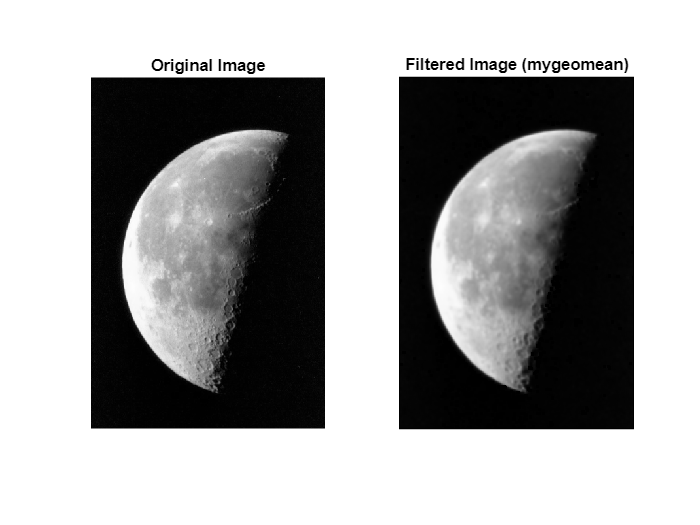


I = imread('moon.tif');
% Applying our geomean function to filter the image with colfilt
I2 = uint8(colfilt(I,[5 5],'sliding',@mygeomean));

% Displaying results
subplot(1,2,1), imshow(I), title('Original Image')
subplot(1,2,2), imshow(I2), title('Filtered Image (mygeomean)')

### **Problem 3-1. Gaussian Filter Mask**

Im = imread('images/Concentric Circles.JPG');      %Import image

%******* Gaussian Filter parameters *******
dev_x   = 0.5;                              %Deviation in x
dev_y   = 6;                                %Deviation in y
size_x  = 6;                                %Mask size in x
size_y  = 5;                                %Mask size in y
rot     = -pi/4;                            %Rotation angle
%******************************************
%Creation of the gaussian filter mask
Gaussian_Filter_Mask = gaussian_filter(dev_x,dev_y,size_x,size_y,rot)        

Gaussian_Filter_Mask =     0.0000    0.0000    0.0002    0.0123    0.0874    0.0826
    0.0000    0.0002    0.0128    0.0936    0.0911    0.0118
    0.0002    0.0127    0.0949    0.0949    0.0127    0.0002
    0.0118    0.0911    0.0936    0.0128    0.0002    0.0000
    0.0826    0.0874    0.0123    0.0002    0.0000    0.0000


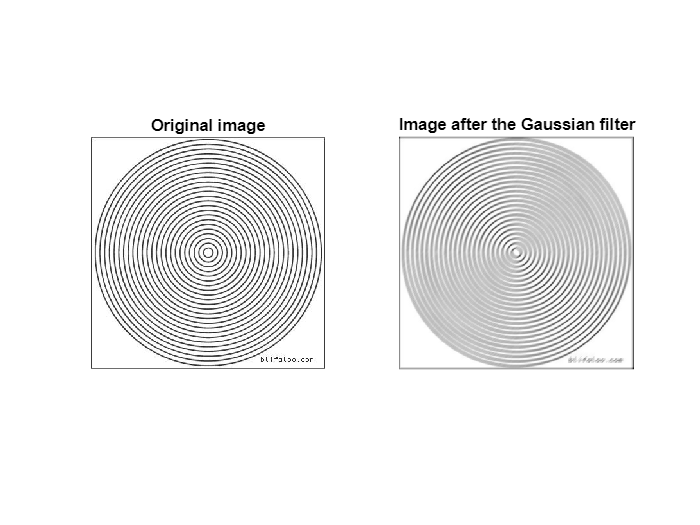

out = imfilter(Im, Gaussian_Filter_Mask);  %Apply the mask to filter the image
figure
subplot(1,2,1); imshow(Im); title("Original image");
subplot(1,2,2); imshow(out); title("Image after the Gaussian filter")

**Use the proper value of µ to center the 2D Gaussian function at the filter mask midpoint (fig. 1).**

To center the 2D Gaussian function at the filter mask midpoint  the mean (µ) has to be (0,0).

**As a test, find the parameters values (deviation, filter size and angle) that must be used in order to obtain an image similar to the image of fig 2b.**

%******* Gaussian Filter parameters *******
dev_x   = 0.5;                              %Deviation in x
dev_y   = 6;                                %Deviation in y
size_x  = 6;                                %Mask size in x
size_y  = 5;                                %Mask size in y
rot     = -pi/4;                            %Rotation angle

**Also, check the effects of noise removing capabilities of this function with this and other images (as Lena.tif) by adding some noise using the function imnoise(). **

Removing noise of concentric circles image

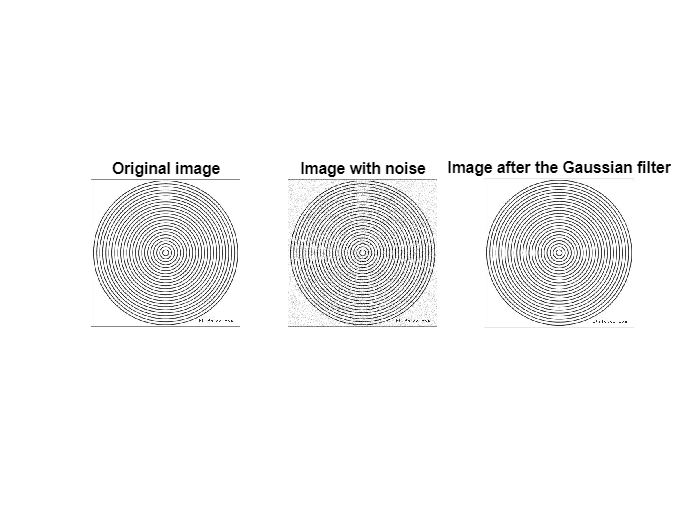

Im2 = imnoise(Im);                          %Image with noise
w = gaussian_filter(0.1,0.1,5,5,0);         %Creation of the gaussian filter mask
out = imfilter(Im, w);                      %Apply the mask to filter the image
figure
%sgtitle("Noise removing") 
subplot(1,3,1); imshow(Im); title("Original image");
subplot(1,3,2); imshow(Im2); title("Image with noise");
subplot(1,3,3); imshow(out); title("Image after the Gaussian filter");

Removing noise of lena image

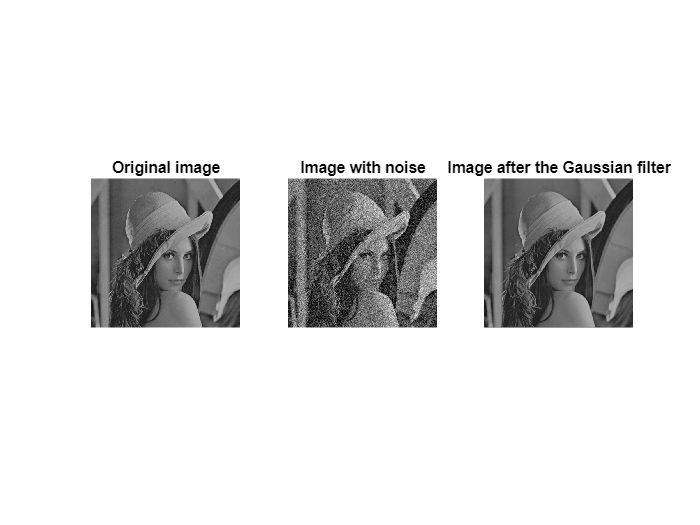

Im = imread('images/lena.gif');      %Import image
Im2 = imnoise(Im);
w = gaussian_filter(0.1,0.1,2,2,0);  
out = imfilter(Im, w);
figure
%sgtitle("Noise removing") 
subplot(1,3,1); imshow(Im); title("Original image");
subplot(1,3,2); imshow(Im2); title("Image with noise");
subplot(1,3,3); imshow(out); title("Image after the Gaussian filter");

**EXTRA BONUS: Using the derivative of the gaussian function generate a mask to enhance the edges of the image in a given direction (same 5 input parameters). Test your mask in the Concentric circles image.**

Im = imread('Concentric Circles.JPG');      %Import image
w = gaussian_filter_2(0.1,0.1,5,5,0);       %Creation of the gaussian filter mask

X =     -2    -1     0     1     2
    -2    -1     0     1     2
    -2    -1     0     1     2
    -2    -1     0     1     2
    -2    -1     0     1     2


Y =     -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1
     0     0     0     0     0
     1     1     1     1     1
     2     2     2     2     2


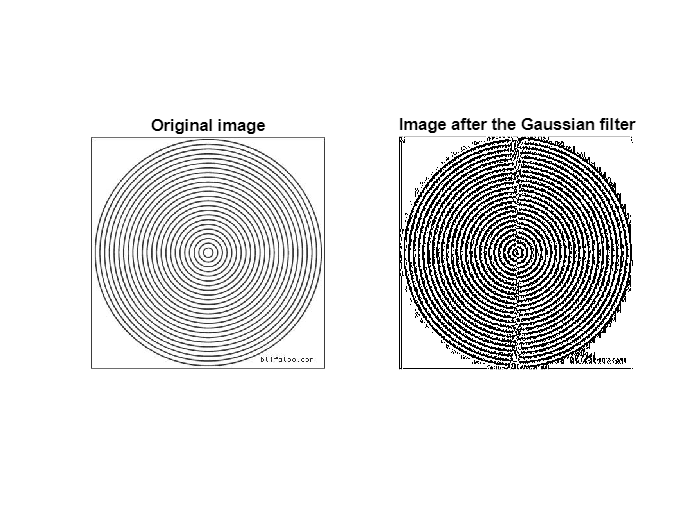

out = imfilter(Im, w);                      %Apply the mask to filter the image
figure
%sgtitle("Noise removing") 
subplot(1,2,1); imshow(Im); title("Original image");
subplot(1,2,2); imshow(out); title("Image after the Gaussian filter");

### **Problem 3-2. **Template matching

Template matching using Cross Correlation and Sum of Absolute Differences

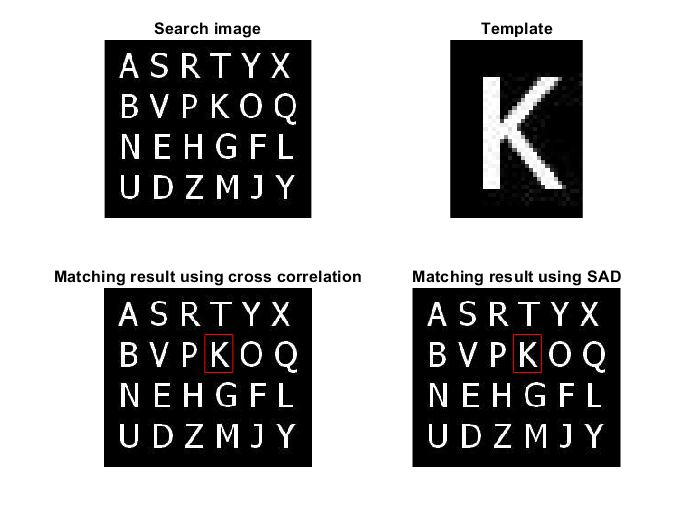

% All the images are stored in "images" folder
% Read Search image
Search_img = imread('images/letters.JPG');

% Read Template image
Template = imread('images/letters_K.JPG');

% Getting x & y coordinates of the bounding box using both techniques
result1 = my_xcorr(Search_img,Template);
result2 = my_SAD(Search_img,Template);

x1 = result1(1); x2 = result1(1);   %  (x,y)
y1 = result1(2); y2 = result2(2);   %    ⬛⬛
X1 = result1(3); X2 = result2(3);   %    ⬛⬛
Y1 = result1(4); Y2 = result2(4);   %       (X,Y)

% Displaying results
figure
subplot(2,2,1),imshow(Search_img);title('Search image');
subplot(2,2,2),imshow(Template);title('Template');
subplot(2,2,3),imshow(Search_img);title('Matching result using cross correlation');
hold on, plot([y1 y1 Y1 Y1 y1],[x1 X1 X1 x1 x1],'r'), hold off   % Drawing bounding box of CC
subplot(2,2,4),imshow(Search_img);title('Matching result using SAD');
hold on, plot([y2 y2 Y2 Y2 y2],[x2 X2 X2 x2 x2],'r'), hold off   % Drawing bounding box of SAD

**Here are shown some already calculated examples.**

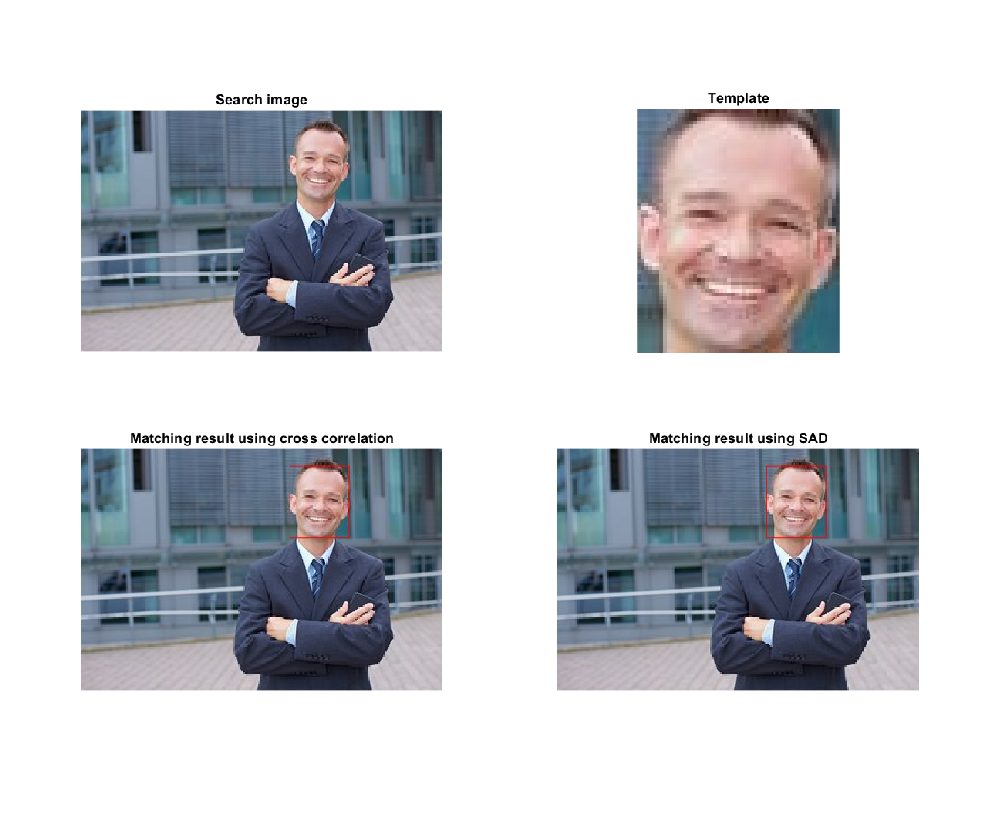

figure; img = imread("images/result_person.png"); imshow(img)

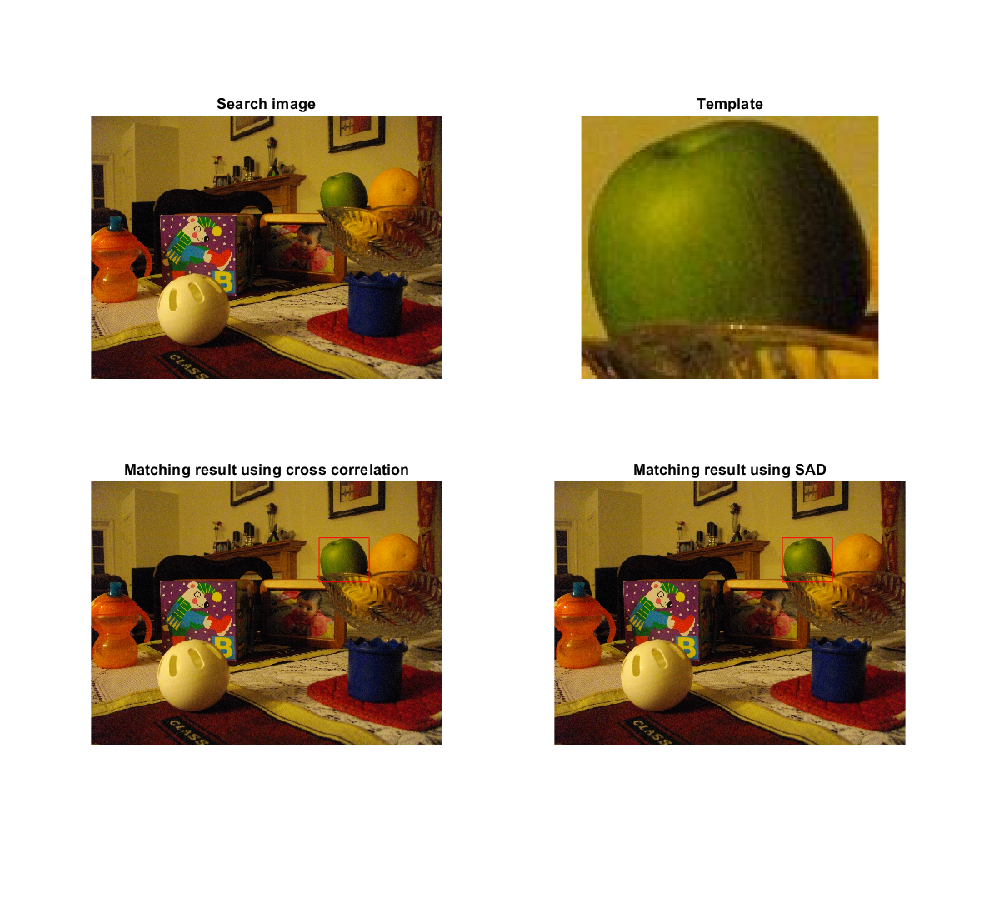

figure; img = imread("images/result_toys_apple.png"); imshow(img)

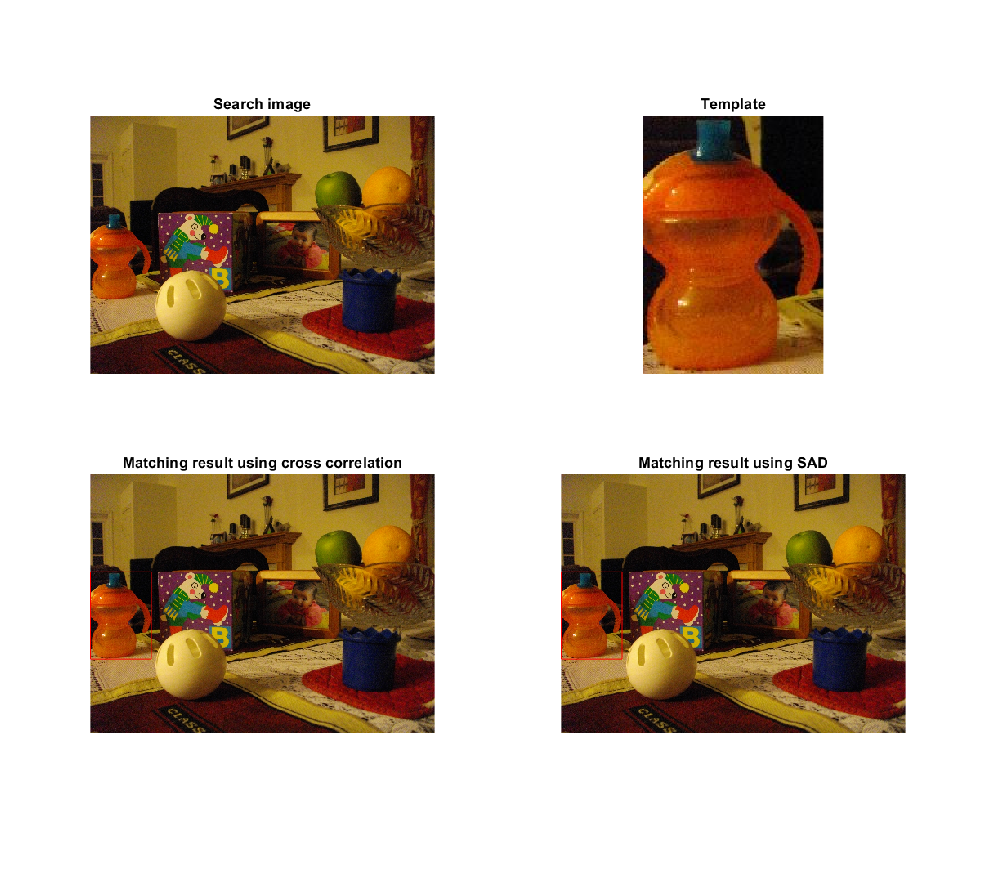

figure; img = imread("images/result_toys_bottle.png"); imshow(img)

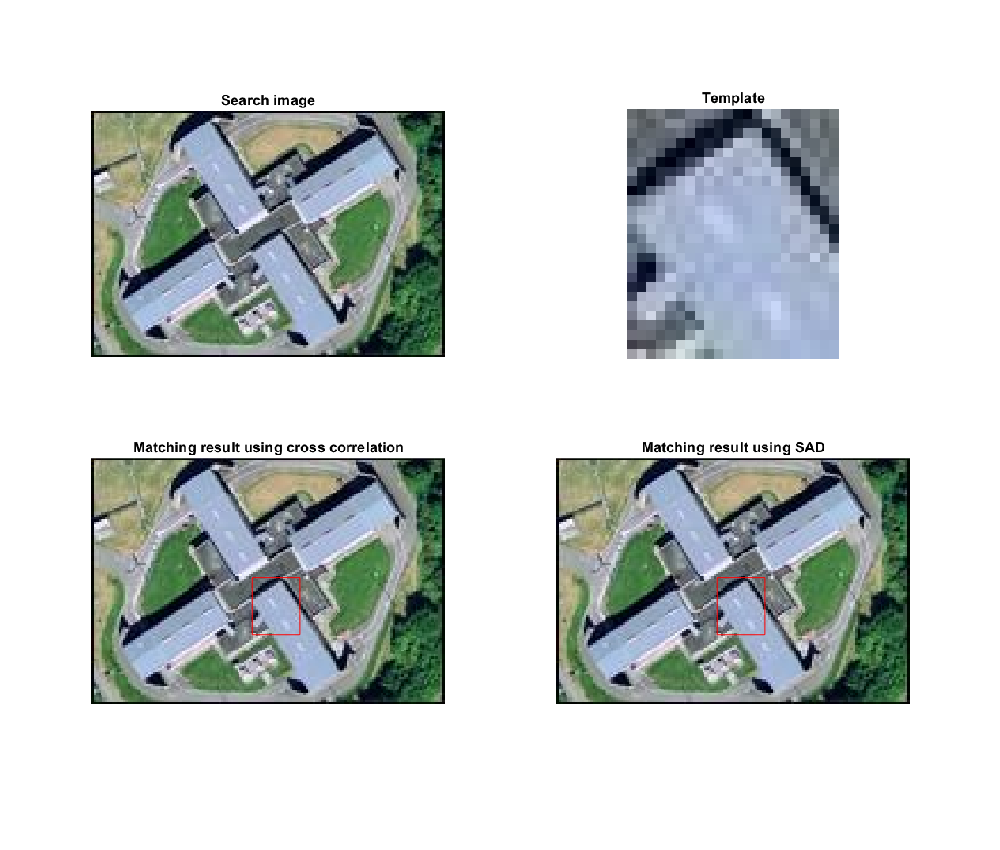

figure; img = imread("images/result_aerial.png"); imshow(img)